%https://www.electrical4u.com/magnetic-reluctance/
clear
filename = 'design_params_ref.xlsx';
[NUM,TXT,RAW] = xlsread(filename);
PI = pi;
for i=1:size(RAW,1)
    eval(RAW(i,1) + " = " + RAW(i,2))
end

rom = 0.5000

valve_seat_outlet_orifice_d = 0.5000

valve_seat_outlet_orifice_rad = 0.5000

valve_seat_outlet_d = 12

valve_seat_outlet_h = 3

valve_seat_outlet_face_oring_din = 0

valve_seat_outlet_face_oring_dout = 0

valve_seat_outlet_face_oring_h = 0

valve_seat_inlet_h = 3

valve_seat_upper_h = 5

valve_seat_upper_face_oring_din = 0

valve_seat_upper_face_oring_dout = 0

valve_seat_upper_face_oring_t = 0

valve_seat_upper_rad_oring_d = 0

valve_seat_upper_rad_oring_t = 0

valve_seat_h = 11

valve_seat_din = 4.5000

valve_cone_cone_d = 4

valve_cone_cone_h = 3

valve_cone_h = 3

valve_cone_hole_d = 1

valve_cone_insert_d = 2

valve_cone_insert_h = 3

valve_spool_d = 4.5000

valve_spool_h = 17

valve_spool_insert_d = 2

valve_spool_insert_h = 3

valve_spool_hole_d = 1

valve_spool_hole_h = 13.6000

valve_spool_hole_2_d = 1

valve_spool_hole_2_h = 10.8800

coil_wire_A = 0.0500

coil_wire_d = 0.2523

coil_h = 20

coil_din = 6

coil_dout = 14

coil_former_din = 6

coil_former_dout = 14

coil_former_h_in = 20

coil_former_h_out = 24

coil_former_hole_d = 4.5000

magnetic_bottom_dout = 14

magnetic_bottom_h = 3

magnetic_bottom_din = 4.5000

magnetic_bottom_face_oring_din = 0

magnetic_bottom_face_oring_dout = 0

magnetic_bottom_face_oring_t = 0

magnetic_top_boss_dout = 4.5000

magnetic_top_boss_din = 2

magnetic_top_boss_h = 12

magnetic_top_h = 5

magnetic_top_dout = 16

magnetic_top_din = 4

magnetic_top_hole_d = 6

magnetic_top_hole_h = 3

magnetic_top_face_oring_din = 0

magnetic_top_face_oring_dout = 0

magnetic_top_face_oring_t = 0

shell_din = 14

shell_dout = 16

shell_h = 27

spring_rod_long_h = 14.5000

spring_rod_long_d = 2

spring_rod_thick_d = 5

spring_rod_thick_h = 1

spring_rod_short_h = 1.5000

spring_rod_short_d = 2

fastener_dout = 18

fastener_h = 5

fastener_face_oring_din = 0

fastener_face_oring_dout = 0

fastener_face_oring_t = 0

casing_din = 16

casing_h = 48

casing_t = 3

casing_thread_h = 5

## Modification

## Sealin Surface

do = 0.5;
r = 0.25;
R = 0.5 * do + r;
fun = @(x) 2*pi*(sqrt(r^2 - x.^2) + R).*sqrt(r^2./(r^2 - x.^2))

fun = function_handle with value:
    @(x)2*pi*(sqrt(r^2-x.^2)+R).*sqrt(r^2./(r^2-x.^2))


S = integral(fun,0,r)

S = 1.6264

Ao = pi * do^2 / 4

Ao = 0.1963

Ap = pi * R^2

Ap = 0.7854

20.5*S

ans = 33.3412

50*Ap

ans = 39.2699

## Magnetic Reluctance

rel_perm = 850

rel_perm = 850

air_perm = 1.25663753*1e-6

air_perm = 1.2566e-06

perm = rel_perm * air_perm

perm = 0.0011

### Magnetic Top

magnetic_top_boss_center_cylnder_r = 0.25 * (magnetic_top_boss_dout + magnetic_top_boss_din)

magnetic_top_boss_center_cylnder_r = 1.6250

shell_center_cylinder_r = 0.25 * (shell_dout + shell_din)

shell_center_cylinder_r = 7.5000

MR_volume_magnetic_top_hor_l = (shell_center_cylinder_r - magnetic_top_boss_center_cylnder_r) * 1e-3

MR_volume_magnetic_top_hor_l = 0.0059

MR_volume_magnetic_top_hor_A =...
    (pi * (magnetic_top_boss_center_cylnder_r + shell_center_cylinder_r) * ... mean cylnder diameter
    (magnetic_top_h - magnetic_top_hole_h)) * 1e-6

MR_volume_magnetic_top_hor_A = 5.7334e-05

MR_magnetic_top_hor = MR_volume_magnetic_top_hor_l / ( perm * MR_volume_magnetic_top_hor_A )

MR_magnetic_top_hor = 9.5933e+04

MR_volume_magnetic_top_ver_l_out = 0.5 * (magnetic_top_h - magnetic_top_hole_h) * 1e-3

MR_volume_magnetic_top_ver_l_out = 1.0000e-03

MR_volume_magnetic_top_ver_A_out = 0.25 * pi * (magnetic_top_dout^2 - shell_din^2) * 1e-6

MR_volume_magnetic_top_ver_A_out = 4.7124e-05

MR_magnetic_top_ver_out = MR_volume_magnetic_top_ver_l_out / ( perm * MR_volume_magnetic_top_ver_A_out ) % mm / (H/m mm^2) -> (m mm / H mm^2) -> 1e3 / H

MR_magnetic_top_ver_out = 1.9867e+04

MR_volume_magnetic_top_ver_l_in = (MR_volume_magnetic_top_ver_l_out + magnetic_top_boss_h) * 1e-3

MR_volume_magnetic_top_ver_l_in = 0.0120

MR_volume_magnetic_top_ver_A_in = 0.25 * pi * (magnetic_top_boss_dout^2 - magnetic_top_boss_din^2) * 1e-6

MR_volume_magnetic_top_ver_A_in = 1.2763e-05

MR_magnetic_top_ver_in = MR_volume_magnetic_top_ver_l_in / ( perm * MR_volume_magnetic_top_ver_A_in ) % mm / (H/m mm^2) -> (m mm / H mm^2) -> 1e3 / H

MR_magnetic_top_ver_in = 8.8033e+05

MR_magnetic_top = (MR_magnetic_top_hor + MR_magnetic_top_ver_out + MR_magnetic_top_ver_in)

MR_magnetic_top = 9.9613e+05

mmf = (200*0.75)*MR_magnetic_top

mmf = 1.4942e+08

### Magnetic Bottom

MR_surface_magnetic_bottom_hor_l = 0.5 * (magnetic_bottom_dout - magnetic_bottom_din) * 1e-3

MR_surface_magnetic_bottom_hor_l = 0.0048

MR_surface_magnetic_bottom_hor_A = pi * 0.5 * (magnetic_bottom_dout + magnetic_bottom_din) * magnetic_bottom_h * 1e-6

MR_surface_magnetic_bottom_hor_A = 8.7179e-05

MR_magnetic_bottom = MR_surface_magnetic_bottom_hor_l / (perm * MR_surface_magnetic_bottom_hor_A)

MR_magnetic_bottom = 5.1010e+04

### Shell

MR_surface_shell_hor_l = 0.5 * (shell_dout - shell_din) * 1e-3

MR_surface_shell_hor_l = 1.0000e-03

MR_surface_shell_hor_A = pi * 0.5 * (shell_dout + shell_din) * magnetic_bottom_h * 1e-6

MR_surface_shell_hor_A = 1.4137e-04

MR_shell_hor = MR_surface_shell_hor_l / (perm * MR_surface_shell_hor_A)

MR_shell_hor = 6.6223e+03

MR_surface_shell_ver_l = (shell_h - 0.5 * magnetic_bottom_h) * 1e-3

MR_surface_shell_ver_l = 0.0255

MR_surface_shell_ver_A = pi * 0.25 * (shell_dout^2 -shell_din^2) * 1e-6

MR_surface_shell_ver_A = 4.7124e-05

MR_shell_ver = MR_surface_shell_ver_l / (perm * MR_surface_shell_ver_A)

MR_shell_ver = 5.0661e+05

MR_shell = MR_shell_ver + MR_shell_hor

MR_shell = 5.1323e+05

### Gap

gap = 0.2

gap = 0.2000

MR_gap_hor_l = gap * 1e-3

MR_gap_hor_l = 2.0000e-04

MR_gap_hor_A = 0.25 * pi * valve_spool_d^2 * 1e-6

MR_gap_hor_A = 1.5904e-05

MR_gap = MR_gap_hor_l / (air_perm * MR_gap_hor_A)

MR_gap = 1.0007e+07

### Valve Spool

MR_surface_valve_spool_hor_l = 0.5 * (valve_spool_d - valve_spool_hole_d) * 1e-3

MR_surface_valve_spool_hor_l = 0.0018

MR_surface_valve_spool_hor_A = pi * 0.5 * (valve_spool_d + valve_spool_hole_d) * magnetic_bottom_h * 1e-6

MR_surface_valve_spool_hor_A = 2.5918e-05

MR_valve_spool_hor = MR_surface_valve_spool_hor_l / (perm * MR_surface_valve_spool_hor_A)

MR_valve_spool_hor = 6.3213e+04

MR_surface_valve_spool_ver_l = (0.5 * shell_h - gap) * 1e-3

MR_surface_valve_spool_ver_l = 0.0133

MR_surface_valve_spool_ver_A = pi * 0.25 * (valve_spool_d^2 - valve_spool_hole_d^2) * 1e-6

MR_surface_valve_spool_ver_A = 1.5119e-05

MR_valve_spool_ver = MR_surface_valve_spool_ver_l / (perm * MR_surface_valve_spool_ver_A)

MR_valve_spool_ver = 8.2357e+05

MR_valve_spool = MR_valve_spool_ver + MR_valve_spool_hor

MR_valve_spool = 8.8679e+05

### Total

MR_total = MR_valve_spool + MR_gap + MR_shell + MR_magnetic_bottom + MR_magnetic_top

MR_total = 1.2454e+07

NI = 1000 * 0.75 % N: # of turns, I: current per turn

NI = 750

flux = NI / MR_total

flux = 6.0221e-05

Fmag = flux^2 / (air_perm * MR_gap_hor_A)

Fmag = 181.4543

rec_max_A = 3.5; % A/mm2;
wire_areas = [0.05 0.1 0.2 0.4 0.7 1]; %mm^2
for i=1:length(wire_areas)
    wire_area = wire_areas(i)
    R_per_km = 18.426905*wire_area^-0.997135
    wire_d = 2 * sqrt(wire_area/pi);
    wire_curr_cap = rec_max_A * wire_area;
    coil_cross_section_A = (coil_dout - coil_din) * coil_h * (2/sqrt(3)); % mm2;
    N = coil_cross_section_A / wire_d^2;
    wire_len = N * pi * (coil_dout + coil_din) * 1e-3;
    wire_R = wire_len * R_per_km * 1e-3;
    sol_V = wire_R * wire_curr_cap;
    sol_P(i) = wire_R * wire_curr_cap^2;
    
    
    flux = N * wire_curr_cap / MR_total;
    Fmag = flux^2 / (air_perm * MR_gap_hor_A);
end

wire_area = 0.0500

R_per_km = 365.3886

wire_area = 0.1000

R_per_km = 183.0574

wire_area = 0.2000

R_per_km = 91.7107

wire_area = 0.4000

R_per_km = 45.9465

wire_area = 0.7000

R_per_km = 26.2973

wire_area = 1

R_per_km = 18.4269

Fmag

Fmag = 83.2031

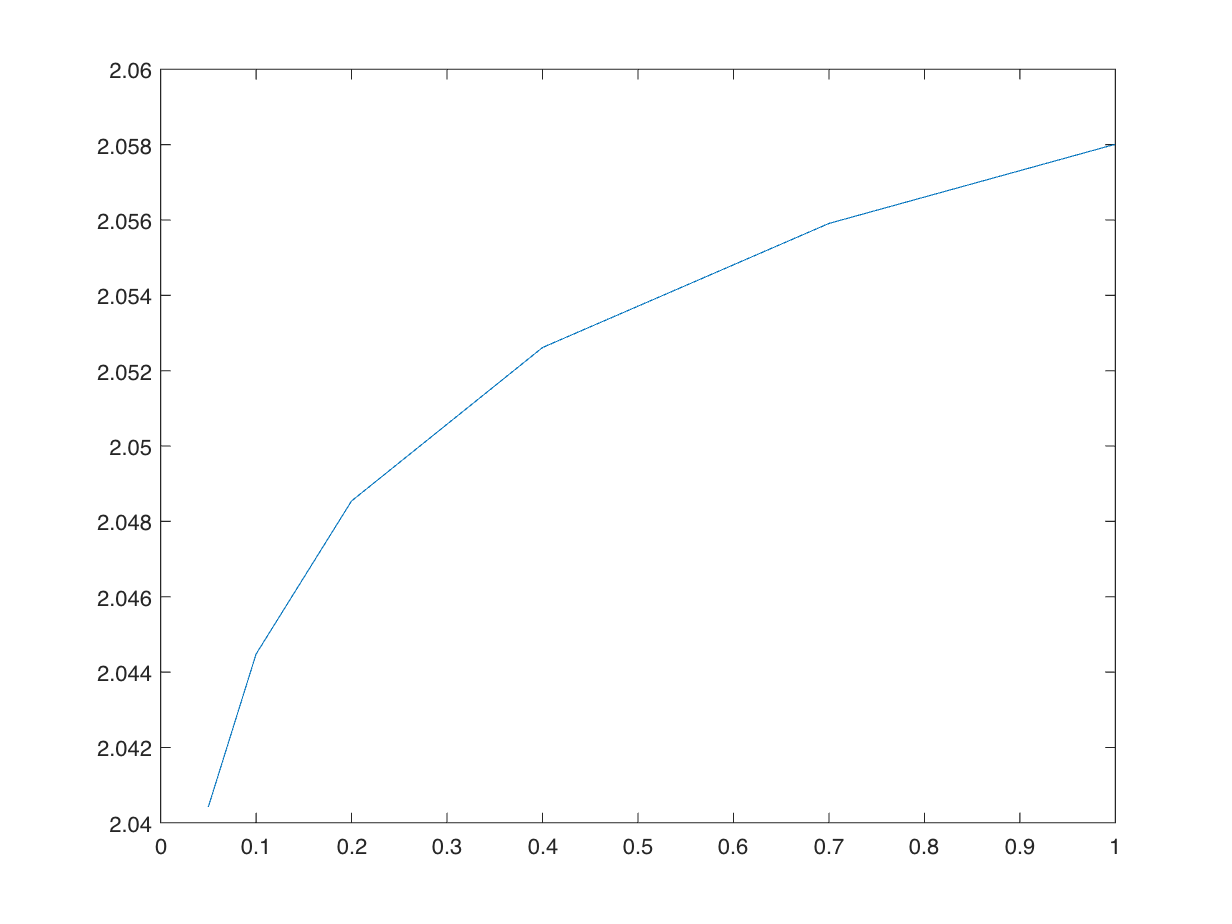

plot(wire_areas,sol_P)